Aplicar un filtre:

I = imread('imatge.jpg');
S = imnoise(I,'salt & pepper', 0.30);

Si la imagen es de mas resolucion, el filtro tiene que aumentar su tamaño, Si no se nota, sube el tamaño. Tiene que sumar 1, para que no tienda al blanco de mas

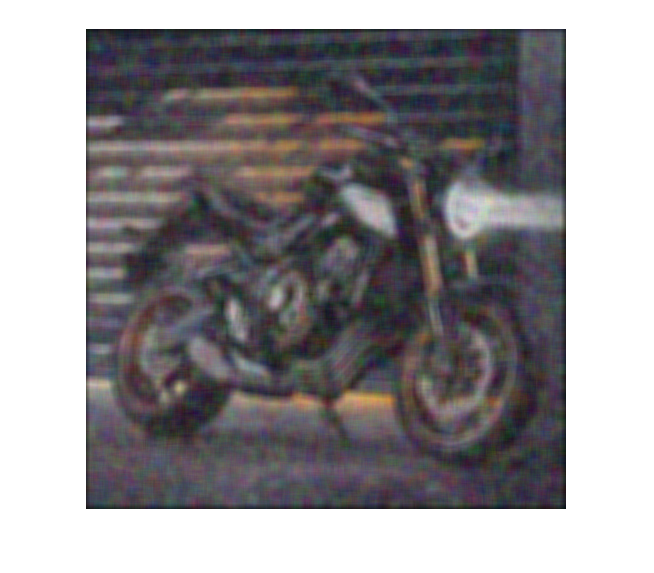

h = ones(10,10)/100;
F = imfilter(S,h);
imshow(F)

Matriu de convolucio

h = ones(30,1);
h(1:14) = 0;
h= h/15;

tipus: gaussian, size, sigma (sigma = size/5)

gaussian = fspecial('gaussian', 10, 10/5);

sobel_h = fspecial('sobel'); %horitzontal
sobel_v = h';
%H = imfilter(S,I);
%imshow(H,[]);

Filtre no lineal

I = imread('imatge.jpg');
S = imnoise(I,'salt & pepper', 0.05);
k = medfilt3(S);

Filtre de mitjana amb guncio colfilt (eficient) (primer columna y despres fila)

f = 10;
c = 10;
%F = colfilt(I, [f c], 'sliding', @mypromig) 

Matrix dimensions must agree.

Error in colfilt (line 133)
    if all(block>=size(a)), % Process the whole matrix at once.